## Load saved linear model analysis object

Contains pre-processed model analyses for PPL203 experiments with high/low density odor presentations. The version contained here used an adjusted R^2 threshold of 0.03 for determining which variables to add to the stepwise model. It does not allow any interaction terms between variables, and uses an odor integration window in the range [30:10:200] optimized separately for each experiment.

parentDir = 'D:\Dropbox (HMS)\2P Data\Imaging Data\GroupedAnalysisData';
dataDir = fullfile(parentDir, 'all_experiments');
figDir = ['C:\Users\Wilson Lab\Documents\MATLAB\2P_code\GroupedAnalysisCode\', ...
    'Manuscript_figure_drafts\Linear_regression_model'];

load(fullfile(parentDir, 'Saved_LinearModel_objects', ...
    'rm_stepThresh_03_no_interactions_30_sec_min_winSize.mat'), 'rm')

## Plot estimated odor response filters

Plotting the trial-averaged odor responses for each experiment that were convolved with the odor onset times to generate the "odorResp" variable for the model fitting. No trials were excluded, even if the fly was moving during the odor presentation.

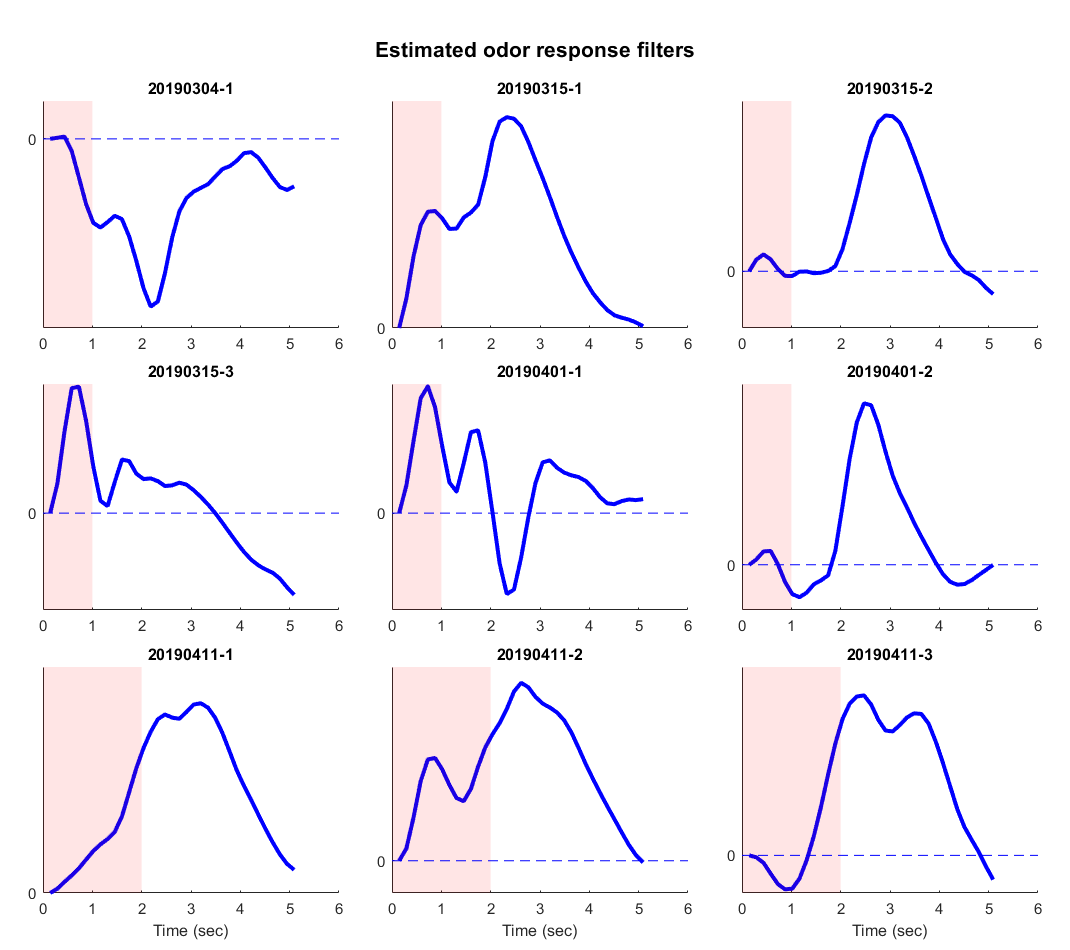

saveFig = 1;
f = figure(1);clf;hold on
f.Color = [1 1 1];
f.Position = [f.Position(1:2), 1070, 950];
if (f.Position(2) + f.Position(4)) > 1000
    f.Position(2) = 1000 - f.Position(4);
end
for iFig = 1:size(rm.sourceData, 1)
    ax = subaxis(3, 3, iFig, 'ml', 0.04, 'mr', 0.03, 'sv', 0.06, 'mb', 0.06); hold on;
    rm.plot_odor_filter(iFig, ax);
    ax.Title.String = ax.Title.String(1:10);
    if iFig < 7
        xlabel(ax, '')
    end
    box off
    ax.YTick = 0;
    xL = xlim();
    yL = ylim();
    if yL(1) ~= 0
        plot(xL, [0 0], '--', 'color', 'blue')
    end
end
suptitle('Estimated odor response filters');
f.Children(2).Children.FontWeight = 'bold';
f.Children(2).Children.FontSize = 16;
f.UserData.sourceDataParams = rm.sourceDataParams;
f.UserData.modelParams = rm.modelParams;
f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
saveFileName = ['estimated_odor_response_filters'];
if saveFig
    save_figure(f, figDir, saveFileName);
end

## Plot trial-averaged behavioral response to odor stim

Same thing as the previous section, but plotting the average change in the fly's net XY speed in response to the odor stim (this is not used in the model)

saveFig = 1;
f = figure(2);clf;hold on
f.Color = [1 1 1];
f.Position = [f.Position(1:2), 1070, 950];
if (f.Position(2) + f.Position(4)) > 1000
    f.Position(2) = 1000 - f.Position(4);
end
allYlim = [];
for iFig = 1:size(rm.sourceData, 1)
    ax = subaxis(3, 3, iFig, 'ml', 0.06, 'mr', 0.03, 'sv', 0.06, 'mb', 0.06); hold on;
    rm.plot_mean_moveSpeed(iFig, ax);
    allYlim(iFig, :) = ylim();
    ax.Title.String = ax.Title.String(1:10);
    if ismember(iFig, [1 4 7])
        ylabel('Move speed (mm/sec)')
    end
    if iFig < 7
        xlabel(ax, '')
    end
    ax.FontSize = 12;
    box off
    xlim([0 6]);
    
end
suptitle('Trial-averaged moveSpeed responses to odor stim');
f.Children(2).Children.FontWeight = 'bold';
f.Children(2).Children.FontSize = 16;
f.UserData.sourceDataParams = rm.sourceDataParams;
f.UserData.modelParams = rm.modelParams;
f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
saveFileName = ['behavioral_odor_responses'];
if saveFig
    save_figure(f, figDir, saveFileName);
end

## Overlay the two previous plots for each experiment

The two variables are plotted on different Y-axes (only the units for the movement speed in mm/sec are shown).

saveFig = 1;
f = figure(3);clf;hold on
f.Color = [1 1 1];
f.Position = [f.Position(1:2), 1070, 950];
if (f.Position(2) + f.Position(4)) > 1000
    f.Position(2) = 1000 - f.Position(4);
end
allYlim = [];
for iFig = 1:size(rm.sourceData, 1)
    ax = subaxis(3, 3, iFig, 'ml', 0.04, 'mr', 0.03, 'sv', 0.06, 'mb', 0.06); hold on;
    rm.plot_mean_moveSpeed(iFig, ax);
    allYlim(iFig, :) = ylim();
    yyaxis right;
    rm.plot_odor_filter(iFig, ax);
    ax.Title.String = ax.Title.String(1:10);
    if iFig < 7
        xlabel(ax, '');
    end
    ax.YAxis(2).Visible = 'off';
    box off;
    ax.YTick = [];
    xlim([0 6]);
    
end
for iPlot = 1:numel(f.Children)
    yyaxis(f.Children(iPlot), 'left');
    f.Children(iPlot).YLim = [min(allYlim(:, 1)), max(allYlim(:, 2))];
end
suptitle('Trial-averaged responses to odor stim (blue = GCaMP, black = move speed)');
f.Children(2).Children.FontWeight = 'bold';
f.Children(2).Children.FontSize = 16;
f.UserData.sourceDataParams = rm.sourceDataParams;
f.UserData.modelParams = rm.modelParams;
f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
saveFileName = ['behavioral_and_estimated_odor_response_filters_overlay'];
if saveFig
    save_figure(f, figDir, saveFileName);
end

## Plot summary of adjusted R^2 values

Compares the full (after drift-correction) models to the same models after removing the odor history variables.

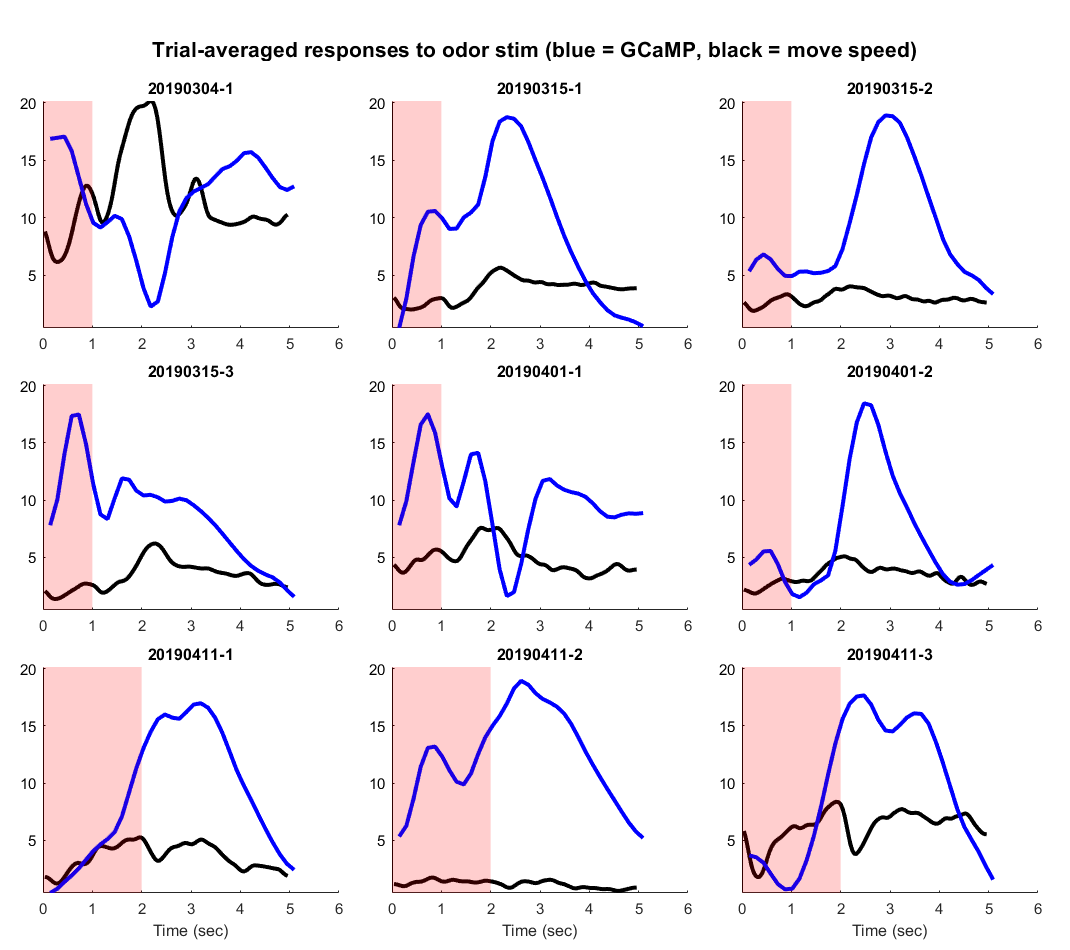

saveFig = 0;
plotArr = [rm.modelData.driftCorrectedMdlAdjR2, ...
    rm.modelData.noOdorHistMdlAdjR2]';
f = figure(3);clf; hold on
f.Color = [1 1 1];
f.Position = [f.Position(1:2), 500, 500];
if (f.Position(2) + f.Position(4)) > 1000

    f.Position(2) = 1000 - f.Position(4);
end
plot(plotArr, '-o', 'Color', rgb('black'), ...
    'markerfacecolor', rgb('green'), 'markerEdgeColor', rgb('green'));
SEM = std_err(plotArr, 2);
errorbar(1:size(plotArr, 1), mean(plotArr, 2)', SEM, '-s', ...
    'color', 'k', 'markerFaceColor', 'k', 'linewidth', 3, 'markerSize', 10)
xlim([0.5, size(plotArr, 1) + 0.5])
ylim([0, 1])
ax = gca();
ax.XTick = 1:size(plotArr, 1);
ax.XTickLabel = {'Drift-corrected', 'No odor history', 'No odor history (re-fit)'};
ylabel('Model adjusted R^2');
ax.FontSize = 14;
% titleStr = '';
if strcmpi(rm.modelParams.upper, 'linear')
    titleStr = 'No interaction terms';
    fileNameStr = 'no';
else
    titleStr = 'Interaction terms allowed';
    fileNameStr = 'with';
end
title({['Adj. R^2 step thresh: ', num2str(rm.modelParams.pEnter)], titleStr});
f.UserData.sourceDataParams = rm.sourceDataParams;
f.UserData.modelParams = rm.modelParams;
f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
if saveFig
    pEnterStr = num2str(rm.modelParams.pEnter);
    saveFileName = ['adj_R2_summary_stepThresh_', pEnterStr(3:end), ...
        '_', fileNameStr, '_interactions'];
    save_figure(f, figDir, saveFileName);
end


## Plot summary of the coefficients used in the drift-corrected models

Also overlays the adjusted R^2 values for each experiment.

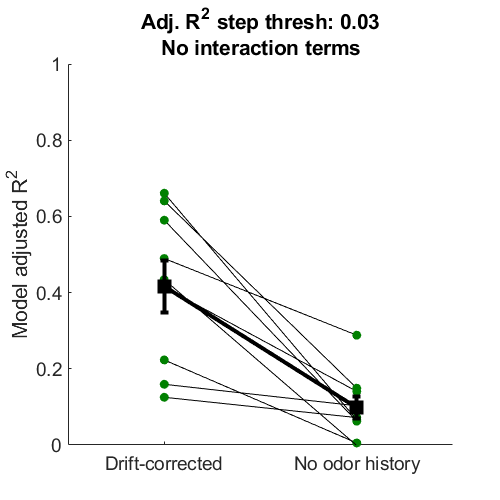

saveFig = 0;

allDcCoeffNames = {};
for iExp = 1:size(rm.modelData, 1)
    allDcCoeffNames = [allDcCoeffNames, rm.modelData.driftCorrectedMdls{iExp}.CoefficientNames];
end
uniqueCoeffs = unique(regexprep(allDcCoeffNames, 'odorHistory_.*', 'odorHistory'));
uniqueCoeffs = uniqueCoeffs(2:end); % Drop intercept term
uniqueCoeffs = uniqueCoeffs([1 3 2]);
coeffArrDc = zeros(numel(uniqueCoeffs), size(rm.modelData, 1));
for iExp = 1:size(rm.modelData, 1)
    for iCoeff = 1:numel(uniqueCoeffs)
        if ismember(uniqueCoeffs{iCoeff}, ...
                regexprep(rm.modelData.driftCorrectedMdls{iExp}.CoefficientNames, ...
                'odorHistory_.*', 'odorHistory'))
            coeffArrDc(iCoeff, iExp) = rm.modelData.driftCorrectedMdls{iExp}.Coefficients.Estimate(...
                strcmp(regexprep(rm.modelData.driftCorrectedMdls{iExp}.CoefficientNames, ...
                'odorHistory_.*', 'odorHistory'), uniqueCoeffs{iCoeff}));
        end
    end
end
coeffTblDc = array2table(coeffArrDc', 'variableNames', uniqueCoeffs, 'rowNames', ...
    rm.modelData.expID);
f = figure(35); clf;
f.Color = [1 1 1];
f.Position = [f.Position(1:2), 750, 950];
if (f.Position(2) + f.Position(4)) > 1000
    f.Position(2) = 1000 - f.Position(4);
end
plotArr = table2array(coeffTblDc);
lim = max(abs([max(plotArr(:)), min(plotArr(:))]));
xSize = size(plotArr, 2);
plotArr(:, end + 1) = -lim;
plotArr(:, end + 1) = lim;
ax = subaxis(1, 1, 1, 'ml', 0.16, 'mt', 0.12, 'mb', 0.03, 'mr', 0.11);
imagesc(plotArr);
cm = colormap(bluewhitered);
xlim([0.5, xSize + 0.5])
ax.XTick = 1:numel(uniqueCoeffs);
ax.XTickLabel = uniqueCoeffs;
ax.XTickLabelRotation = 30;
ax.YTick = 1:size(coeffTblDc, 1);
ax.YTickLabel = rm.modelData.expID;
ax.XAxisLocation = 'top';
ax.FontSize = 14;
pos = ax.Position;
cb = colorbar();
cb.Position(1) = sum(ax.Position([1 3])) + 0.03;
ax.Position = pos;
hold on;
xL = xlim();
yL = ylim();
for iCol = 1:(numel(uniqueCoeffs))
    if iCol == 1
        plot([iCol iCol] - 0.5, yL, 'color', 'k', 'linewidth', 1.5)
    end
    plot([iCol iCol] + 0.5, yL, 'color', 'k', 'linewidth', 1.5)
end
for iRow = 1:(numel(rm.modelData.expID))
    if iRow == 1
        plot(xL, [iRow iRow] - 0.5, 'color', 'k', 'linewidth', 1.5)
    end
    plot(xL, [iRow iRow] + 0.5, 'color', 'k', 'linewidth', 1.5)
    text(2.6, iRow, ['   Adj. R^2 = ', num2str(rm.modelData.driftCorrectedMdlAdjR2(iRow), 2)], ...
        'FontSize', 12);
end
title('Drift-corrected model coefficients')
f.UserData.sourceDataParams = rm.sourceDataParams;
f.UserData.modelParams = rm.modelParams;
f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
if saveFig
    pEnterStr = num2str(rm.modelParams.pEnter);
    saveFileName = ['model_coeff_summary_driftCorrected_stepThresh_', pEnterStr(3:end), ...
        '_', fileNameStr, '_interactions'];
    save_figure(f, figDir, saveFileName);
end

## Plot predicted vs. measured fluorescence

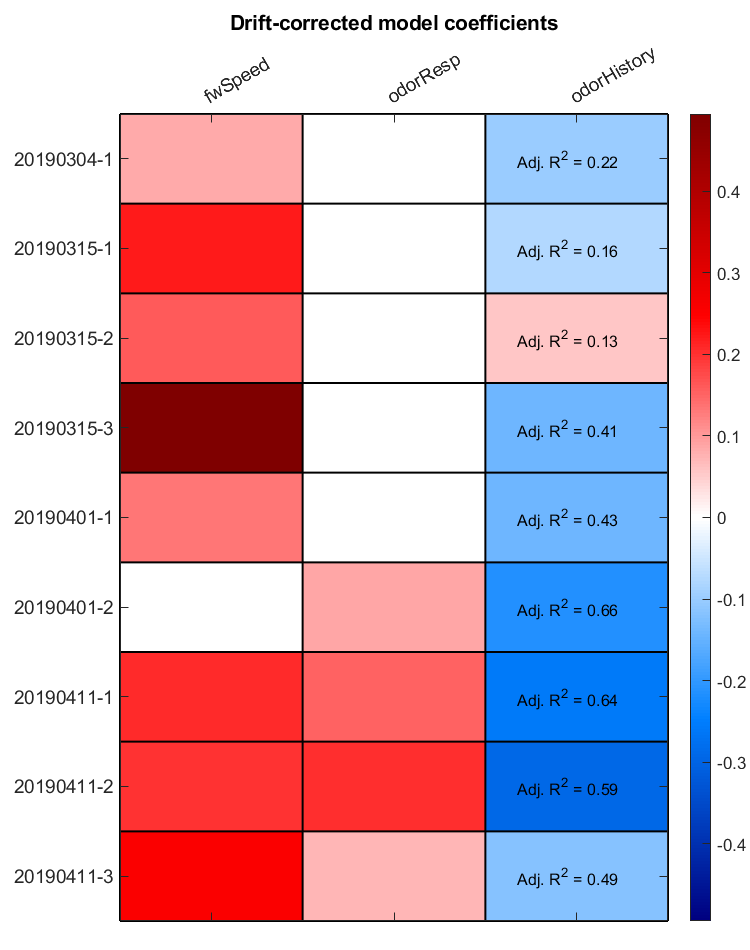

saveFigs = 1;

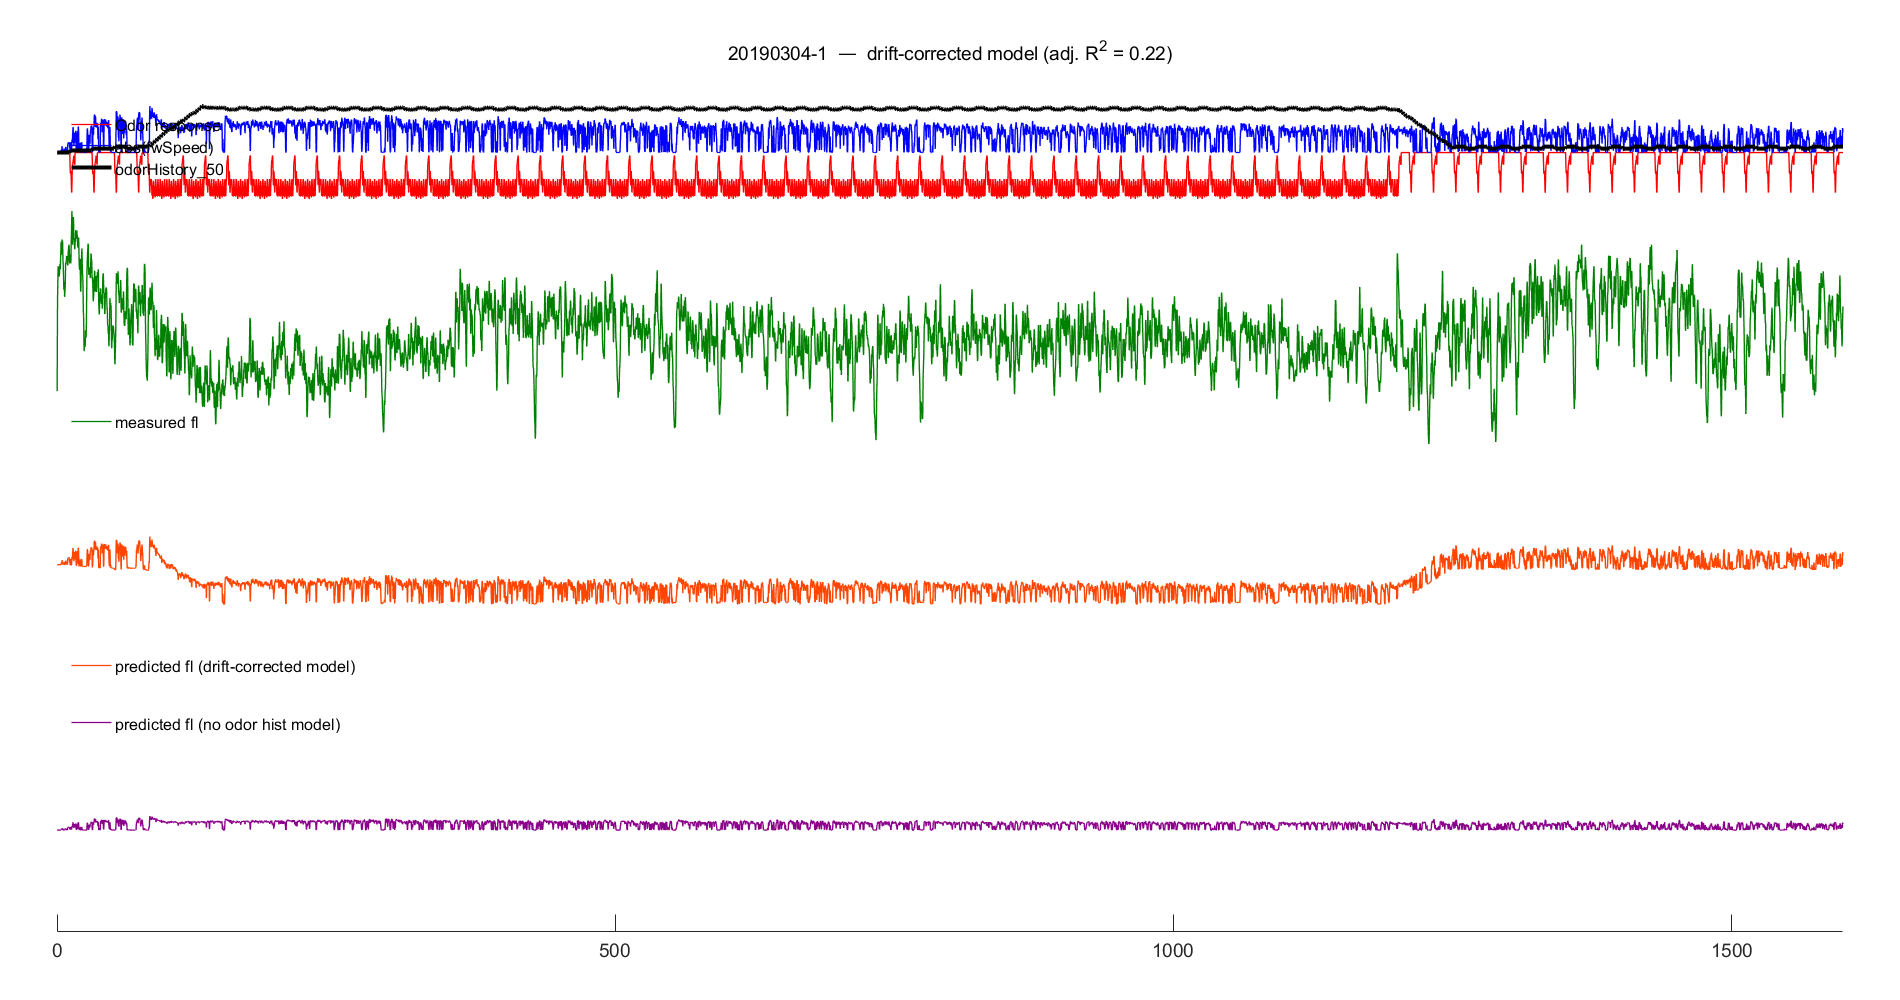

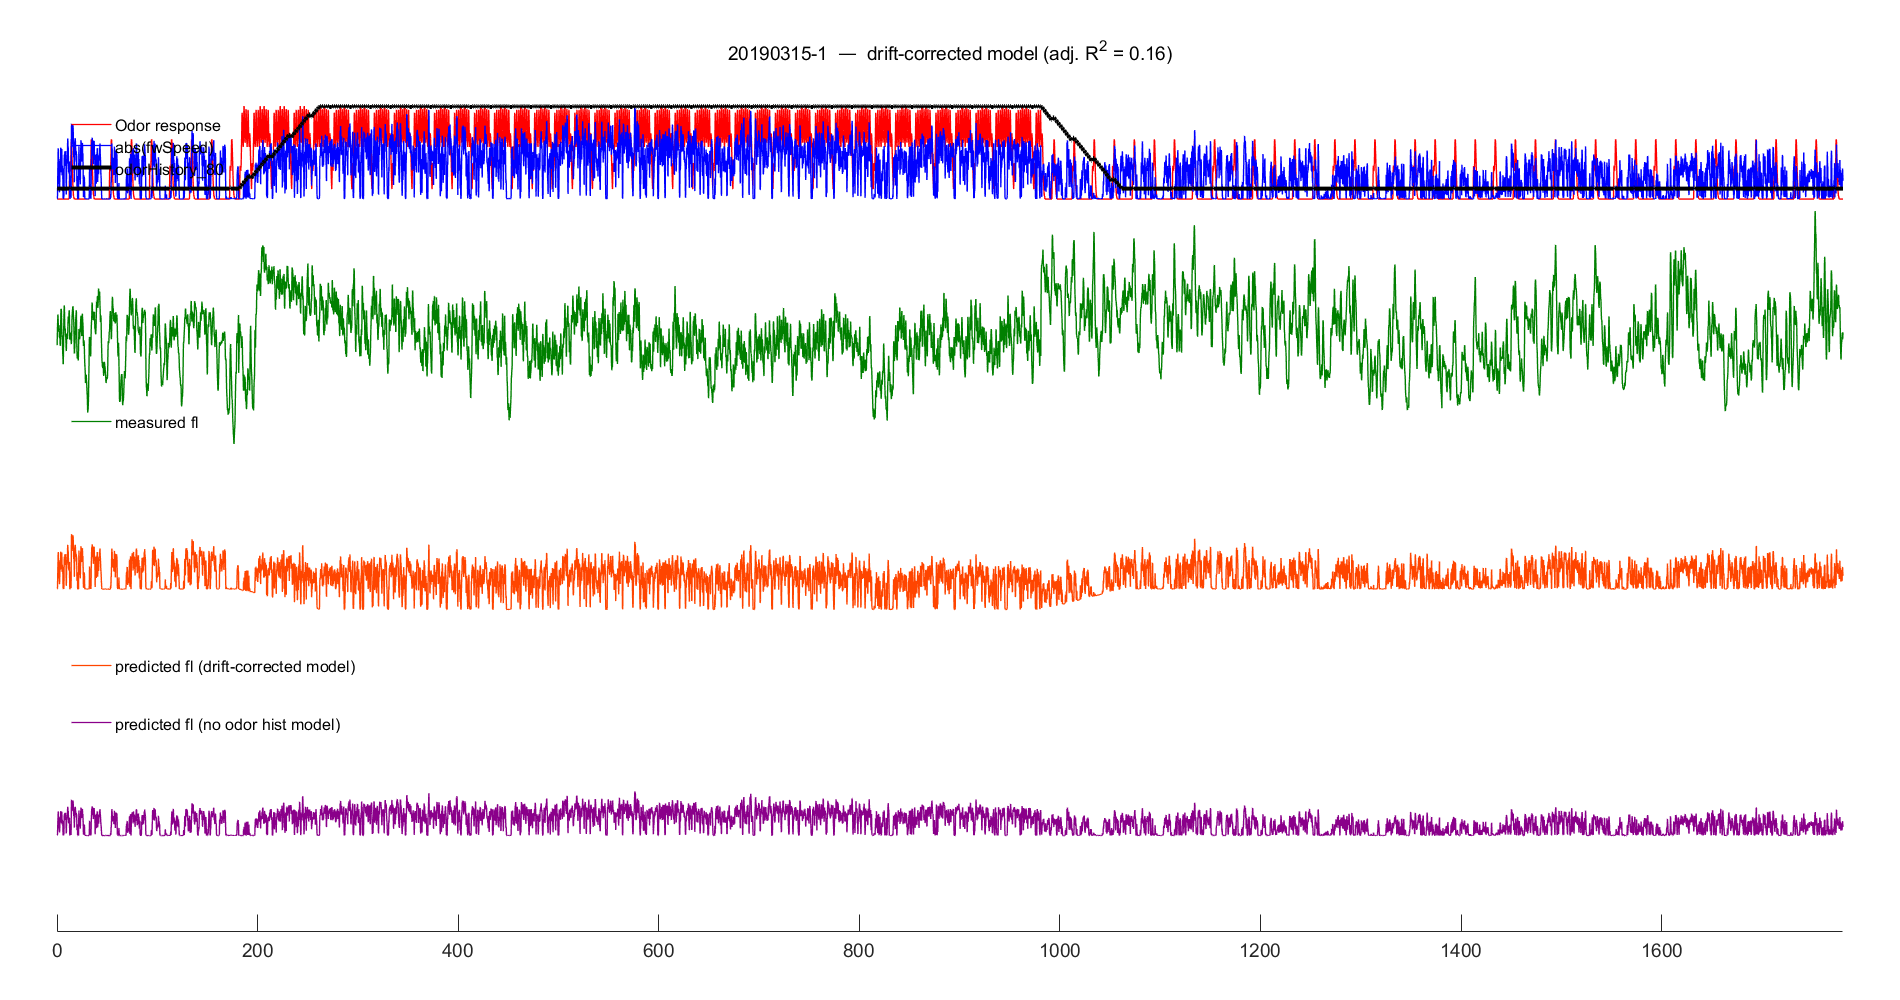

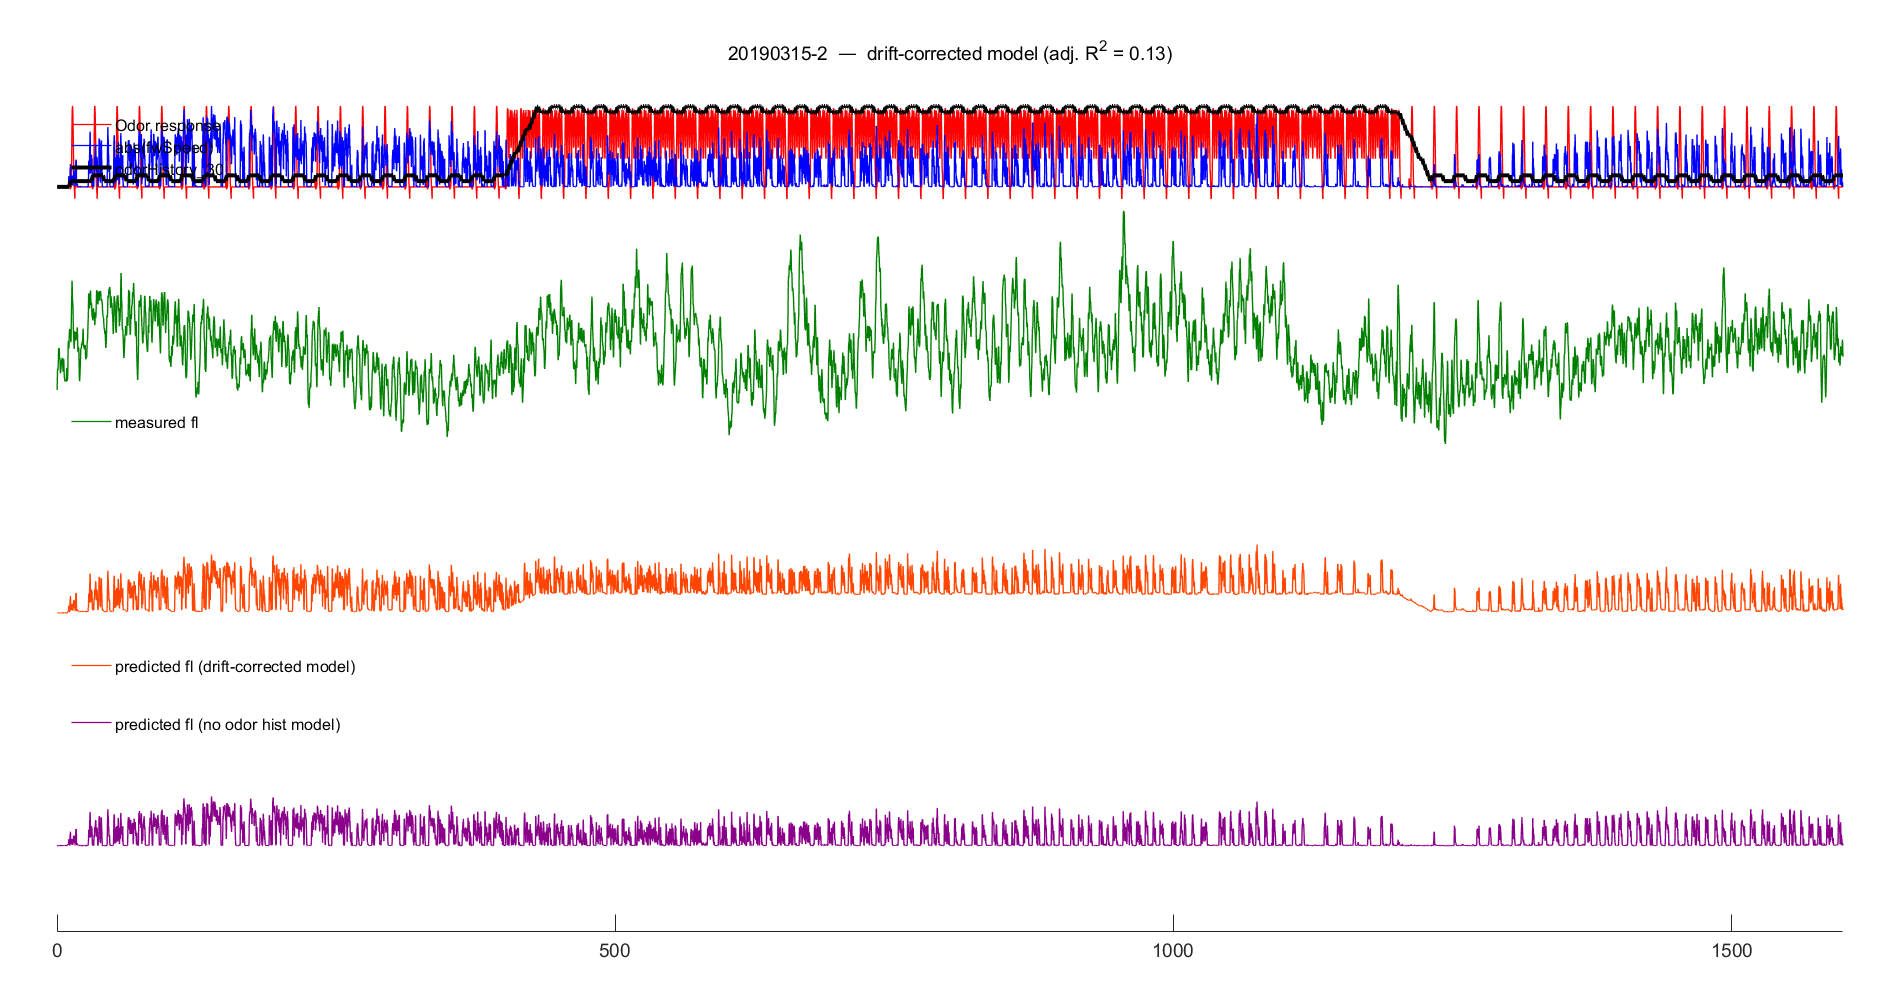

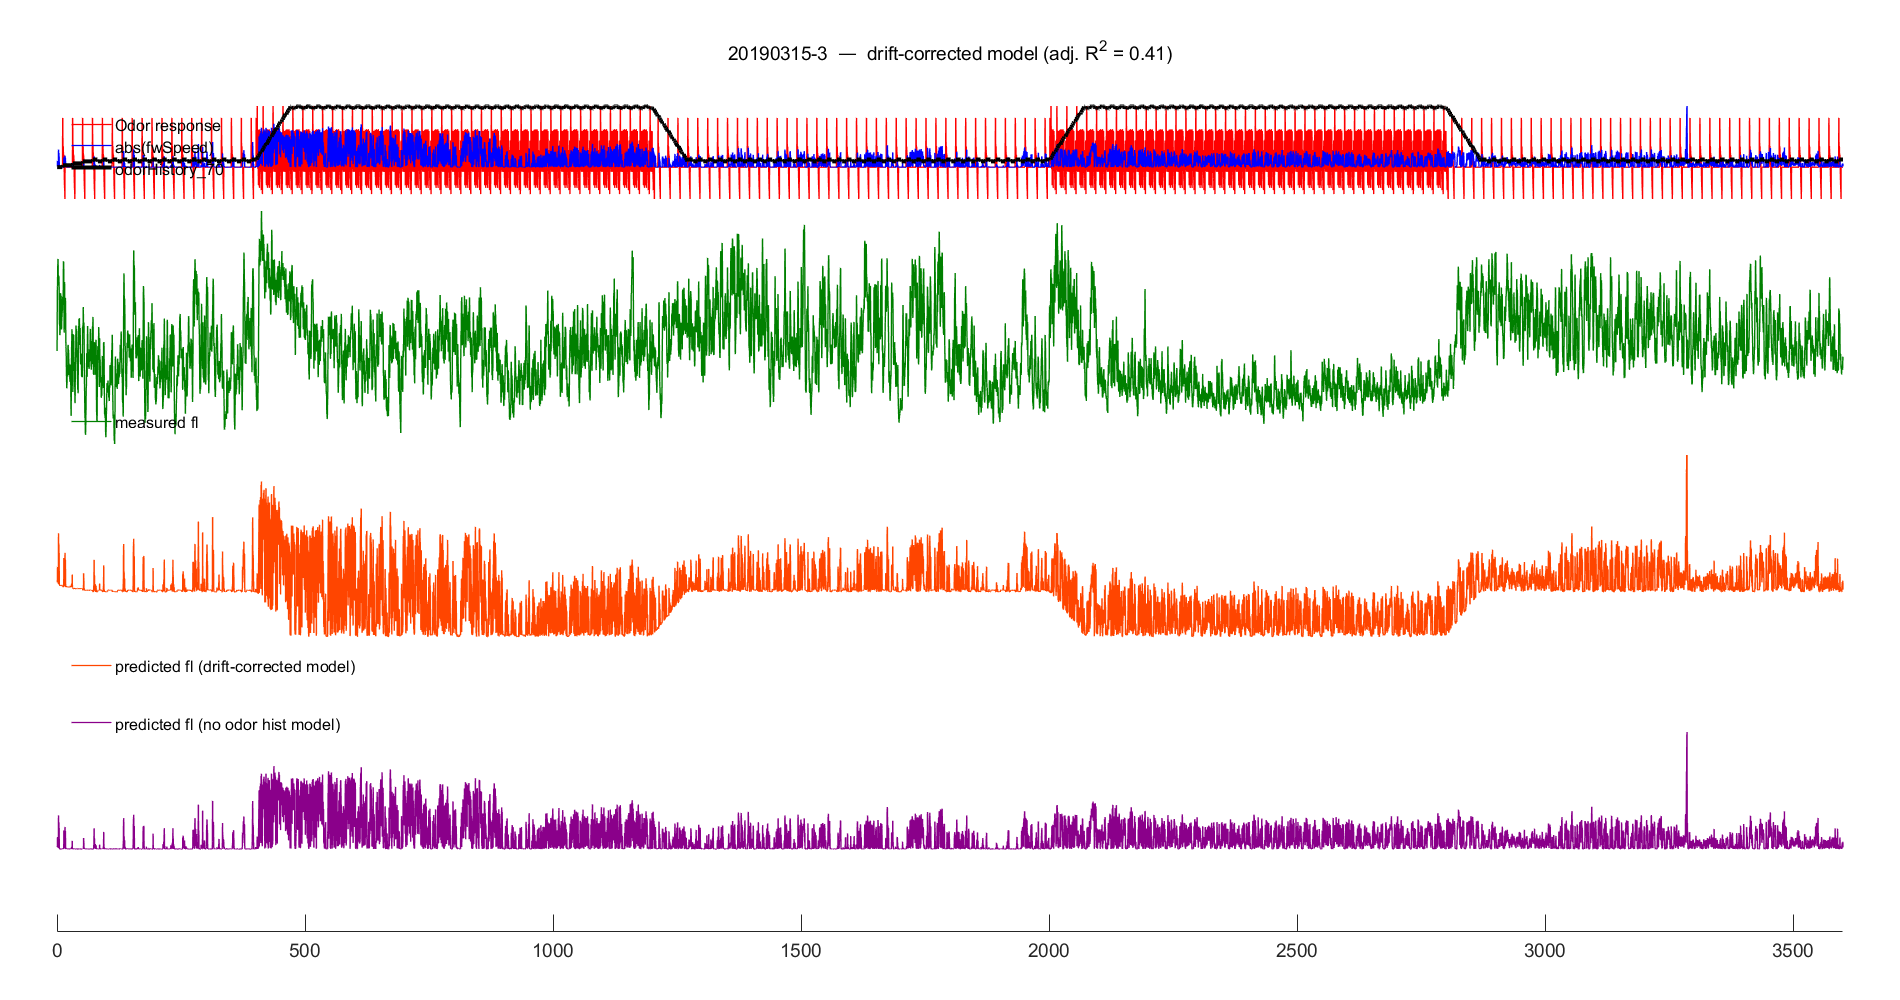

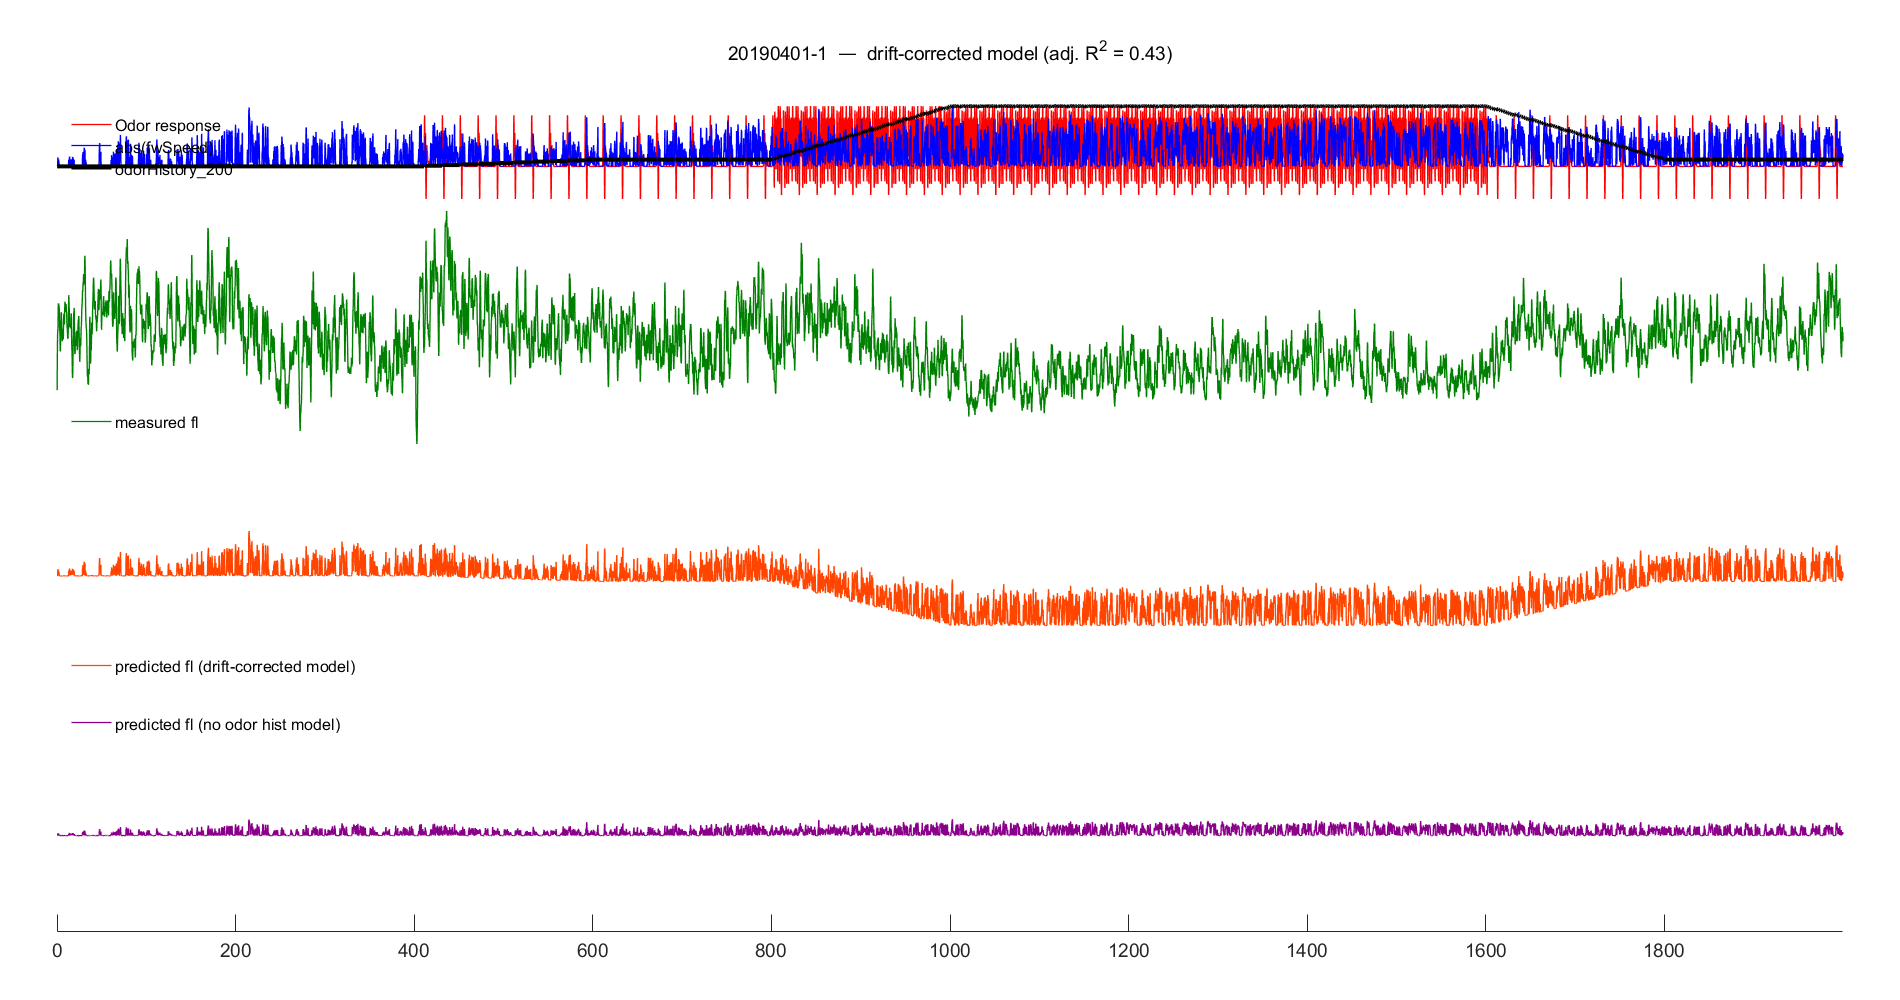

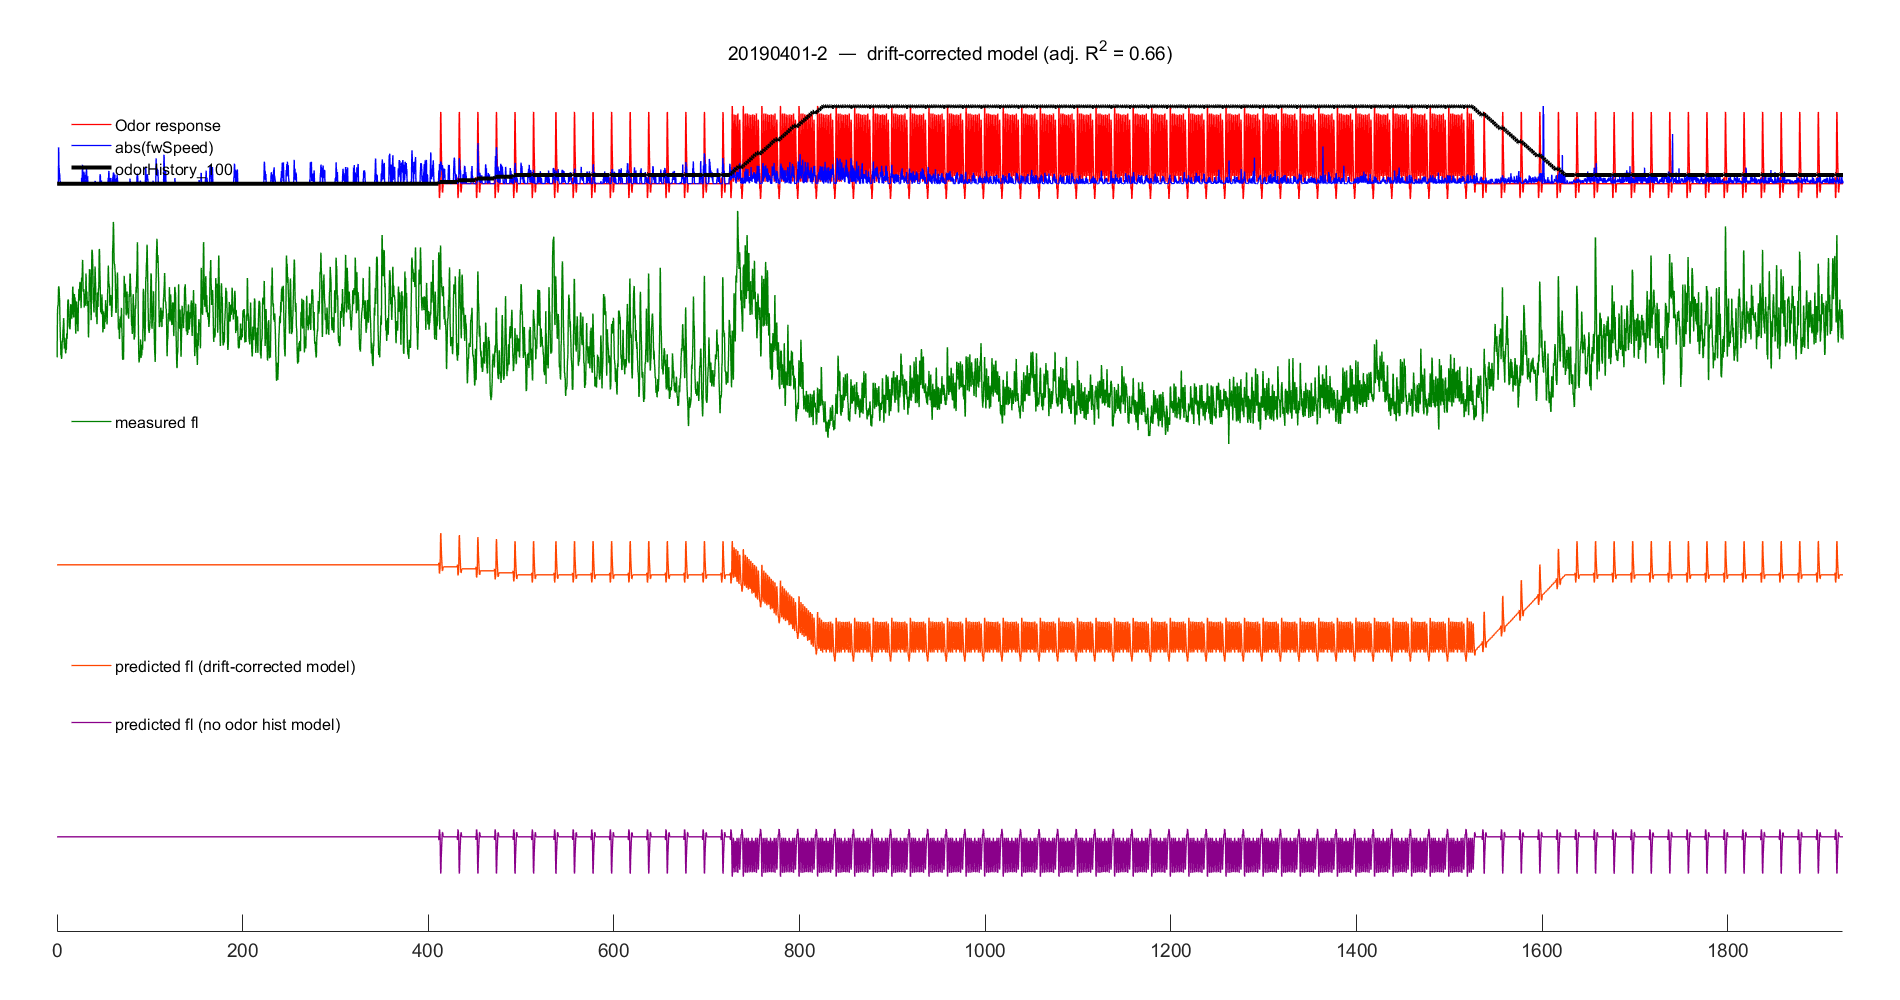

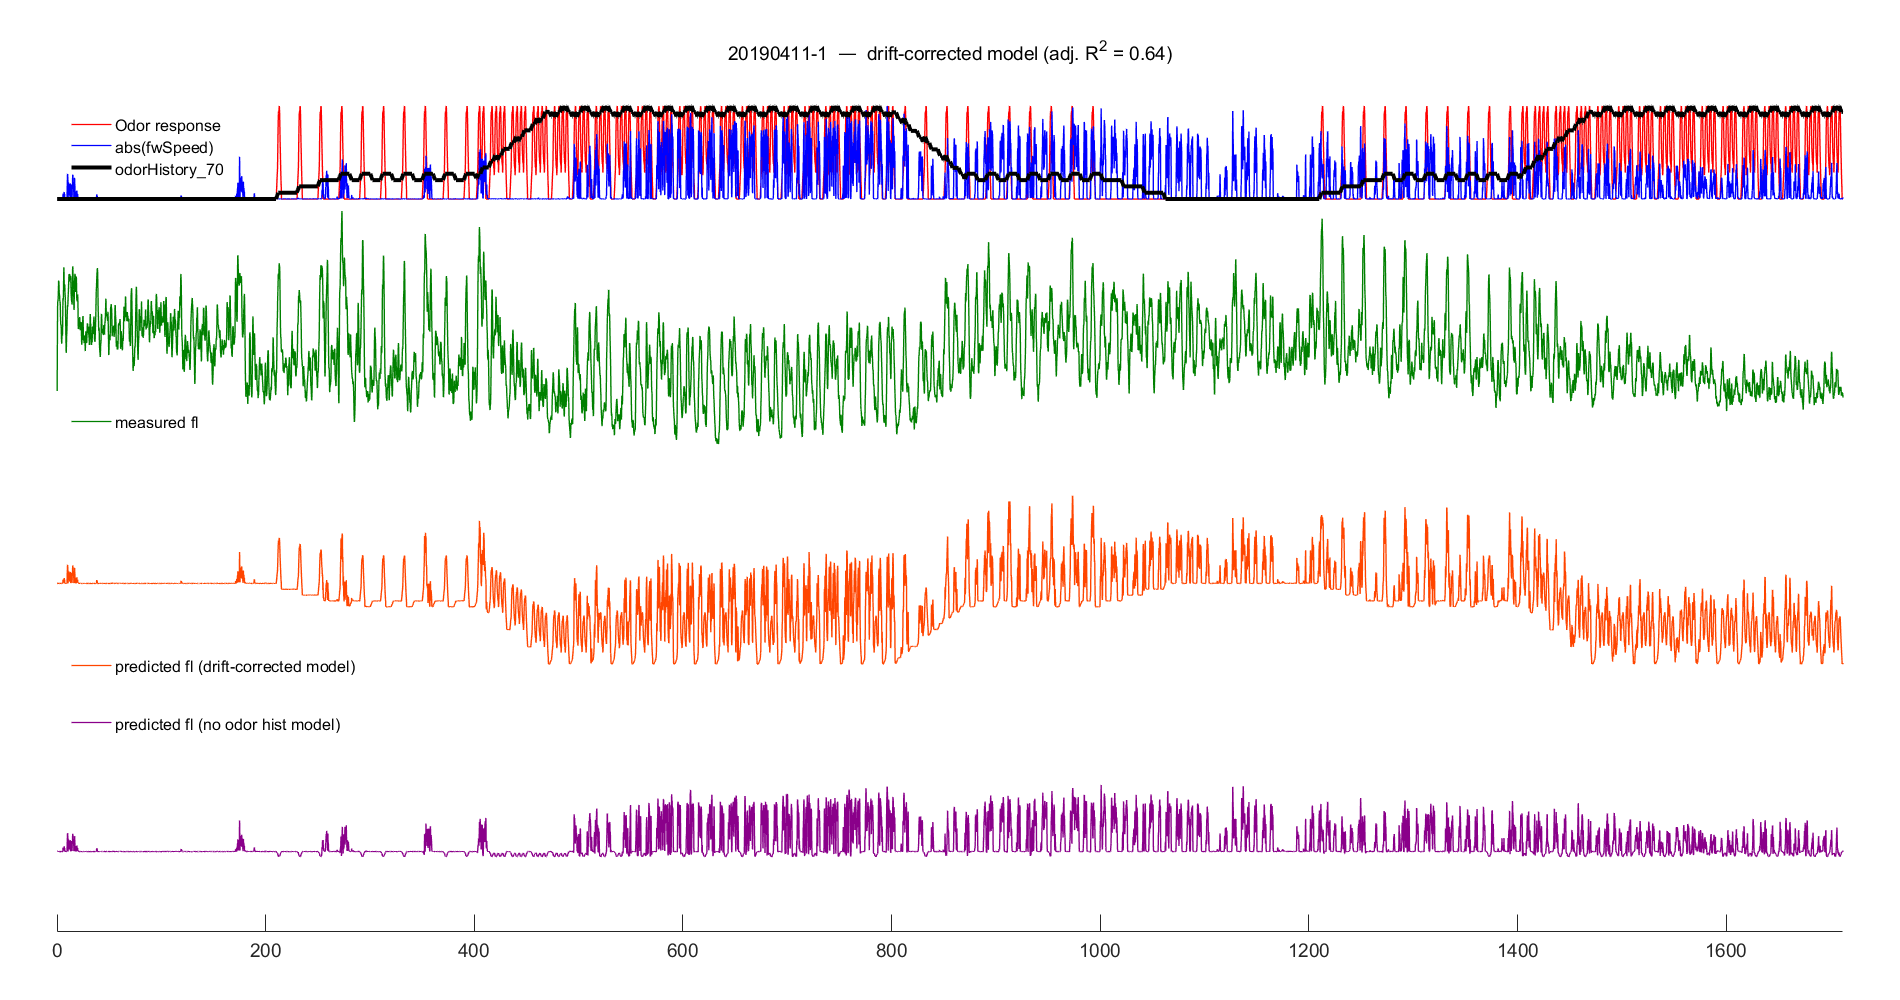

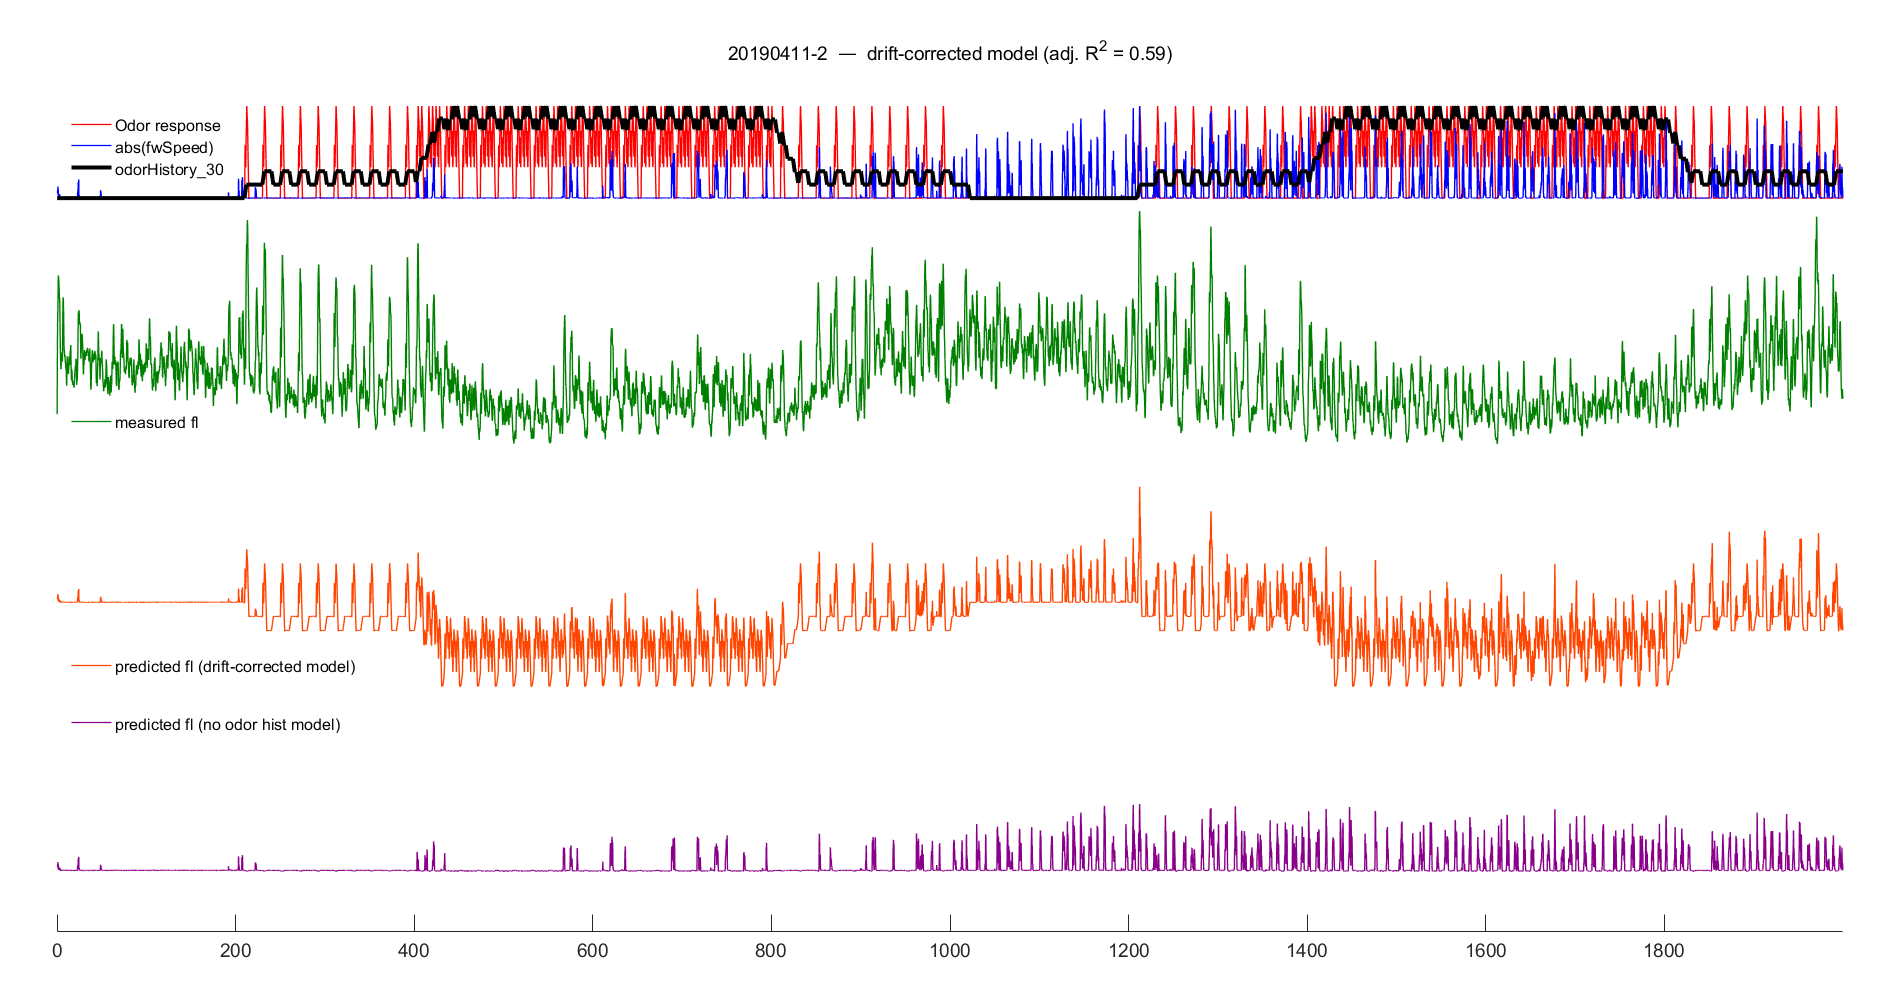

fileNameStr = 'fullExp_';
figDims = [1900 1000];

predictorVars = {'odorHistory', 'odorResp', 'fwSpeed'}; % odorHistory, odorResp, fwSpeed, yawSpeed
legendLocs = {'sw', 'sw', 'nw', 'nw'};
% legendLocs = {'best', 'best', 'best', 'best'};
xLimits = {[], [], [300 600], [1800 3200], [700 1900], [300 1000], [300 600], [100 1100], [1000 1600]}';
xLimits = repmat({[]}, 1, 10);
% xLimits = {[400 800], [200 600], [1 500], [1 500], [], [200 600], [500 800], [1 400]}';

legendStr = {'predicted fl', 'measured fl'};
for iExp = 1:size(rm.modelData, 1)
    
    f = figure(iExp + 100); clf;
    f.Color = [1 1 1];
    if ~isempty(figDims)
        f.Position(3:4) = figDims;
    end
    
    currModelData = rm.modelData(iExp, :);
    currSourceData = rm.sourceData(iExp, :);
    
    bestWinSize = currModelData.bestWinSizes;
    
    fullDataTbl = currModelData.fullDataTbl{:};
    fullDataTbl = fullDataTbl(~isnan(fullDataTbl.fl), :);
    
    legendStr = {'predicted fl (drift-corrected model)', 'predicted fl (no odor hist model)', ...
        'measured fl'};
    dcPredFl = currModelData.driftCorrectedMdlPredFl{:};
    nohPredFl = currModelData.noOdorHistMdlPredFl{:};
    measuredFl = currModelData.driftCorrectedMdlMeasuredFl{:};
    xx = currSourceData.volTimes{:}(1:numel(measuredFl))';
    xL = xLimits{iExp};
    if isempty(xL)
        xL = [0 xx(end)];
    end
    
    % Measured Fl data
    ax = subaxis(24, 1, 4:10, 'mt', 0.05, 'mb', 0.07, 'ml', 0.03, 'mr', 0.03, 'sv', 0.01); hold on;
    plot(xx, measuredFl, 'linewidth', 1, 'color', rgb('green'));
    %     plot(xx, dcPredFl, 'linewidth', 1, 'color', rgb('orangered'));
    ax.YTickLabel = [];
    legend(legendStr{3}, 'fontsize', 12, 'Location', legendLocs{1}, 'autoupdate', 'off', 'box', ...
        'off');
    ax.FontSize = 14;
    ax.YTickLabel = [];
    ax.XTickLabel = [];
    ax.XLim = xL;
    ax.YLim = [min(measuredFl) max(measuredFl)];
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    %     title([currModelData.expID{:}, '  —  drift-corrected model (adj. R^2 = ', ...
    %             num2str(currModelData.driftCorrectedMdlAdjR2, 2), ')'])
    box off;
    
    % Drift-corrected model
    ax = subaxis(24, 1, 11:17, 'mt', 0.05, 'mb', 0.07, 'ml', 0.03, 'mr', 0.03, 'sv', 0.01); hold on;
    %     plot(xx, measuredFl, 'linewidth', 1, 'color', rgb('green'));
    plot(xx, dcPredFl, 'linewidth', 1, 'color', rgb('orangered'));
    ax.YTickLabel = [];
    legend(legendStr{1}, 'fontsize', 12, 'Location', legendLocs{2}, 'autoupdate', 'off', 'box', ...
        'off');
    ax.FontSize = 14;
    ax.YTickLabel = [];
    ax.XTickLabel = [];
    ax.XLim = xL;
    ax.YLim = [min(measuredFl) max(measuredFl)];
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    box off;
    
    % No-odor history model
    ax = subaxis(24, 1, 18:24); hold on
    %     plot(xx, measuredFl, 'linewidth', 1, 'color', rgb('green'));
    plot(xx, nohPredFl, 'linewidth', 1, 'color', rgb('darkmagenta'));
    ax.FontSize = 14;
    %     ax.XTickLabel = [];
    ax.YTickLabel = [];
    ax.XLim = xL;
    legend(legendStr{2}, 'fontsize', 12, 'Location', legendLocs{3}, 'autoupdate', 'off', ...
        'box', 'off');
    box off
    %     ax.XAxis.Visible = 'off';
    ax.YAxis.Visible = 'off';
    ax.YLim = [min(measuredFl) max(measuredFl)];
    
    % Integrated odor history
    ax = subaxis(24, 1, 1:3); hold on
    legendStr = {};
    if any(strcmpi('odorResp', predictorVars))
        odorResp = fullDataTbl.odorResp(~logical(sum(isnan(table2array(fullDataTbl)), 2)));
        plot(xx, odorResp ./ max(abs([min(odorResp), max(odorResp)])), 'color', rgb('red'), ...
            'linewidth', 1);
        legendStr{end + 1} = 'Odor response';
    end
    if any(strcmpi('fwSpeed', predictorVars))
        plot(xx, fullDataTbl.fwSpeed(~logical(sum(isnan(table2array(fullDataTbl)), 2))), '-', ...
            'color', rgb('blue'), 'linewidth', 1);
        legendStr{end + 1} = 'abs(fwSpeed)';
    end
    if any(strcmpi('yawSpeed', predictorVars))
        plot(xx, fullDataTbl.yawSpeed(~logical(sum(isnan(table2array(fullDataTbl)), 2))), 'color', ...
            rgb('red'));
        legendStr{end + 1} = 'yawSpeed';
    end
    if any(strcmpi('odorHistory', predictorVars))
        varName = ['odorHistory_', num2str(bestWinSize)];
        plot(xx, fullDataTbl.(varName)(~logical(sum(isnan(table2array(fullDataTbl)), 2))), '-', ...
            'color', rgb('black'), 'linewidth', 3);
        legendStr{end + 1} = regexprep(varName, '_', '\\_');
    end
    ax.FontSize = 14;
    ax.YTickLabel = [];
    ax.XTickLabel = [];
    ax.XLim = xL;
    box off
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    legend(legendStr, 'fontsize', 12, 'Location', legendLocs{4}, 'autoupdate', 'off', 'box', ...
        'off');
    xlabel('Time (sec)')
    suptitle([currModelData.expID{:}, '  —  drift-corrected model (adj. R^2 = ', ...
        num2str(currModelData.driftCorrectedMdlAdjR2, 2), ')'])
    f.UserData.sourceDataParams = rm.sourceDataParams;
    f.UserData.modelParams = rm.modelParams;
    f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
    if saveFigs
        figTitle = ['predictedVsMeasuredFl_', fileNameStr, currModelData.expID{:}];
        save_figure(f, figDir, figTitle);
    end
end